pause on;

n = 2;
f = @(x) log(x + 2);
max_error = eps;

w = @(x) 1 ./ sqrt(1 - x .^ 2);

x = chebyshev_roots(n);
w_x = w(x);
y = f(x);

base = chebyshev_I_base(n);
phi = base(x);

W = diag(w_x);
coeffs = (phi' * W * phi) \ (phi' * W * y');

% Approximating the function using a linear space input
xx = linspace(-1, 1, 100);
approx = (base(xx) * coeffs)'

approx =     0.0194    0.0358    0.0520    0.0681    0.0841    0.1000    0.1158    0.1315    0.1470    0.1625    0.1778    0.1930    0.2082    0.2232    0.2380    0.2528    0.2675    0.2820    0.2964    0.3108    0.3250    0.3390    0.3530    0.3669    0.3806    0.3943    0.4078    0.4212    0.4345    0.4477    0.4608    0.4737    0.4866    0.4993    0.5119    0.5245    0.5369    0.5491    0.5613    0.5734    0.5853    0.5971    0.6089    0.6205    0.6320    0.6433    0.6546    0.6658    0.6768    0.6877


max_iterations = 50;
iter = 0;

err = mean((f(xx) - approx).^2);
while err > max_error
    %fprintf("### DEGREE: %d | ERROR: %.16e\n\n", n, err);
    n
    err
    n = n + 1; % going one degree up

    x = chebyshev_roots(n);
    w_x = w(x);
    y = f(x);

    base = chebyshev_I_base(n);
    phi = base(x);

    W = diag(w_x);
    coeffs = (phi' * W * phi) \ (phi' * W * y');

    approx = (base(xx) * coeffs)'
    err = mean((f(xx) - approx).^2);

    iter = iter + 1;
    if iter >= max_iterations
        disp("=== Maximum iterations reached! ===");
        break;
    end
end

n = 2

err = 7.9854e-05

approx =     0.0040    0.0227    0.0412    0.0595    0.0775    0.0953    0.1129    0.1303    0.1474    0.1643    0.1810    0.1975    0.2138    0.2299    0.2457    0.2614    0.2769    0.2921    0.3072    0.3221    0.3368    0.3513    0.3656    0.3797    0.3937    0.4074    0.4210    0.4344    0.4477    0.4607    0.4736    0.4864    0.4990    0.5114    0.5237    0.5358    0.5477    0.5595    0.5712    0.5827    0.5941    0.6053    0.6164    0.6274    0.6382    0.6489    0.6595    0.6699    0.6802    0.6904


n = 3

err = 3.3040e-06

approx =     0.0009    0.0205    0.0397    0.0587    0.0773    0.0957    0.1138    0.1316    0.1491    0.1663    0.1833    0.1999    0.2164    0.2326    0.2485    0.2642    0.2797    0.2949    0.3099    0.3247    0.3393    0.3537    0.3679    0.3818    0.3956    0.4092    0.4225    0.4358    0.4488    0.4616    0.4743    0.4868    0.4992    0.5114    0.5234    0.5353    0.5471    0.5587    0.5702    0.5815    0.5927    0.6038    0.6147    0.6256    0.6363    0.6469    0.6573    0.6677    0.6780    0.6881


n = 4

err = 1.5366e-07

approx =     0.0002    0.0201    0.0396    0.0587    0.0776    0.0961    0.1142    0.1321    0.1496    0.1669    0.1839    0.2006    0.2170    0.2332    0.2491    0.2647    0.2801    0.2953    0.3102    0.3250    0.3395    0.3538    0.3679    0.3818    0.3955    0.4090    0.4223    0.4354    0.4484    0.4612    0.4739    0.4864    0.4987    0.5109    0.5229    0.5348    0.5466    0.5582    0.5696    0.5810    0.5922    0.6033    0.6143    0.6252    0.6359    0.6465    0.6570    0.6675    0.6778    0.6880


n = 5

err = 7.7210e-09

approx =     0.0000    0.0200    0.0396    0.0588    0.0777    0.0962    0.1144    0.1322    0.1498    0.1670    0.1840    0.2007    0.2171    0.2332    0.2491    0.2647    0.2801    0.2953    0.3102    0.3249    0.3394    0.3537    0.3678    0.3816    0.3953    0.4088    0.4222    0.4353    0.4483    0.4611    0.4738    0.4863    0.4986    0.5108    0.5229    0.5348    0.5465    0.5581    0.5696    0.5810    0.5922    0.6034    0.6143    0.6252    0.6360    0.6466    0.6571    0.6676    0.6779    0.6881


n = 6

err = 4.0973e-10

approx =     0.0000    0.0200    0.0396    0.0588    0.0777    0.0962    0.1144    0.1323    0.1498    0.1671    0.1840    0.2007    0.2171    0.2332    0.2491    0.2647    0.2801    0.2952    0.3102    0.3249    0.3394    0.3536    0.3677    0.3816    0.3953    0.4088    0.4222    0.4353    0.4483    0.4611    0.4738    0.4863    0.4986    0.5108    0.5229    0.5348    0.5465    0.5582    0.5697    0.5810    0.5923    0.6034    0.6144    0.6252    0.6360    0.6466    0.6572    0.6676    0.6779    0.6881


n = 7

err = 2.2640e-11

approx =     0.0000    0.0200    0.0396    0.0588    0.0777    0.0962    0.1144    0.1323    0.1498    0.1671    0.1840    0.2007    0.2171    0.2332    0.2491    0.2647    0.2801    0.2952    0.3102    0.3249    0.3394    0.3536    0.3677    0.3816    0.3953    0.4088    0.4222    0.4353    0.4483    0.4611    0.4738    0.4863    0.4986    0.5108    0.5229    0.5348    0.5465    0.5582    0.5697    0.5810    0.5923    0.6034    0.6144    0.6252    0.6360    0.6466    0.6572    0.6676    0.6779    0.6881


n = 8

err = 1.2904e-12

approx =     0.0000    0.0200    0.0396    0.0588    0.0777    0.0962    0.1144    0.1323    0.1498    0.1671    0.1840    0.2007    0.2171    0.2332    0.2491    0.2647    0.2801    0.2952    0.3102    0.3249    0.3394    0.3536    0.3677    0.3816    0.3953    0.4088    0.4222    0.4353    0.4483    0.4611    0.4738    0.4863    0.4986    0.5108    0.5229    0.5348    0.5465    0.5582    0.5697    0.5810    0.5923    0.6034    0.6144    0.6252    0.6360    0.6466    0.6572    0.6676    0.6779    0.6881


n = 9

err = 7.5381e-14

approx =     0.0000    0.0200    0.0396    0.0588    0.0777    0.0962    0.1144    0.1323    0.1498    0.1671    0.1840    0.2007    0.2171    0.2332    0.2491    0.2647    0.2801    0.2952    0.3102    0.3249    0.3394    0.3536    0.3677    0.3816    0.3953    0.4088    0.4222    0.4353    0.4483    0.4611    0.4738    0.4863    0.4986    0.5108    0.5229    0.5348    0.5465    0.5582    0.5697    0.5810    0.5923    0.6034    0.6144    0.6252    0.6360    0.6466    0.6572    0.6676    0.6779    0.6881


n = 10

err = 4.4915e-15

approx =     0.0000    0.0200    0.0396    0.0588    0.0777    0.0962    0.1144    0.1323    0.1498    0.1671    0.1840    0.2007    0.2171    0.2332    0.2491    0.2647    0.2801    0.2952    0.3102    0.3249    0.3394    0.3536    0.3677    0.3816    0.3953    0.4088    0.4222    0.4353    0.4483    0.4611    0.4738    0.4863    0.4986    0.5108    0.5229    0.5348    0.5465    0.5582    0.5697    0.5810    0.5923    0.6034    0.6144    0.6252    0.6360    0.6466    0.6572    0.6676    0.6779    0.6881


n = 11

err = 2.7200e-16

approx =     0.0000    0.0200    0.0396    0.0588    0.0777    0.0962    0.1144    0.1323    0.1498    0.1671    0.1840    0.2007    0.2171    0.2332    0.2491    0.2647    0.2801    0.2952    0.3102    0.3249    0.3394    0.3536    0.3677    0.3816    0.3953    0.4088    0.4222    0.4353    0.4483    0.4611    0.4738    0.4863    0.4986    0.5108    0.5229    0.5348    0.5465    0.5582    0.5697    0.5810    0.5923    0.6034    0.6144    0.6252    0.6360    0.6466    0.6572    0.6676    0.6779    0.6881


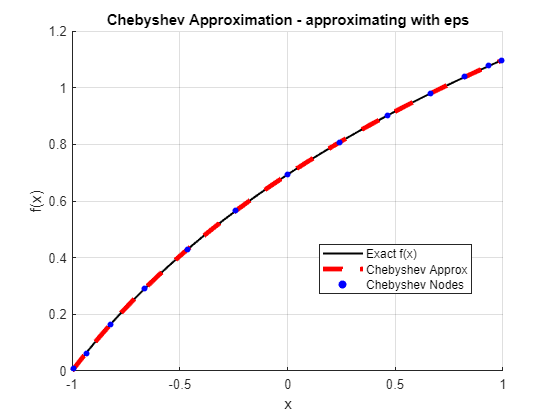

figure;
hold on;

grid on;

plot(xx, f(xx), 'k-', 'LineWidth', 1.5, 'DisplayName', 'Exact f(x)');
plot(xx, approx, 'r--', 'LineWidth', 3.5, 'DisplayName', 'Chebyshev Approx');
scatter(x, y, 20, 'bo', 'filled', 'DisplayName', 'Chebyshev Nodes');

legend("Location", "best");
title('Chebyshev Approximation - approximating with eps');
xlabel('x');
ylabel('f(x)');